load("ResultsAnalysisData.mat")

t = out.inputs.x.time;

input_x = out.inputs.x.Data;
input_y = out.inputs.y.Data;
input_z = out.inputs.z.Data;
input_yaw = rad2deg(out.inputs.yaw.Data);

true_x = out.truePose.Estimatex.Data;
true_y = out.truePose.Estimatey.Data;
true_z = out.truePose.Estimatez.Data;
true_roll = rad2deg(out.truePose.EstimateRoll.Data);
true_pitch = rad2deg(out.truePose.EstimatePitch.Data);
true_yaw = rad2deg(out.truePose.EstimateYaw.Data);

true_m1 = out.trueMotors.m1.Data;
true_m2 = out.trueMotors.m2.Data;
true_m3 = out.trueMotors.m3.Data;
true_m4 = out.trueMotors.m4.Data;

sim_x = out.simPose.x.Data;
sim_y = out.simPose.y.Data;
sim_z = out.simPose.z.Data;
sim_roll = rad2deg(out.simPose.roll.Data);
sim_pitch = rad2deg(out.simPose.pitch.Data);
sim_yaw = rad2deg(out.simPose.yaw.Data);

sim_m1 = out.simMotors.Motor_1_PWM.Data;
sim_m2 = out.simMotors.Motor_2_PWM.Data;
sim_m3 = out.simMotors.Motor_3_PWM.Data;
sim_m4 = out.simMotors.Motor_4_PWM.Data;

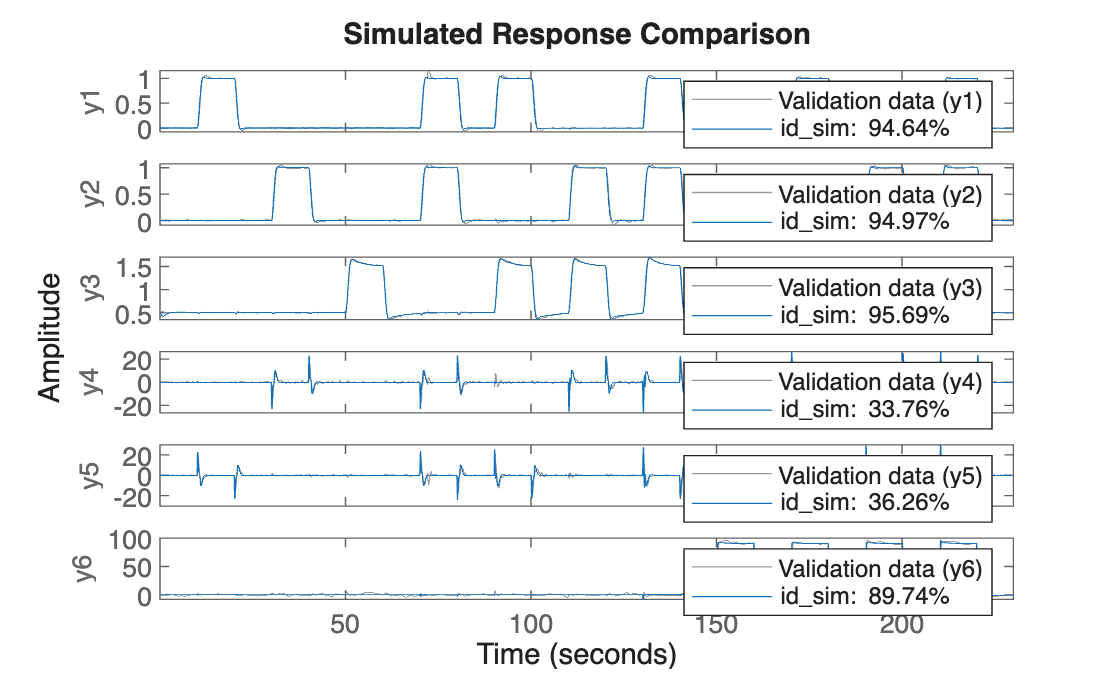

id_sim = iddata([sim_x, sim_y, sim_z, sim_roll, sim_pitch, sim_yaw],[input_x, input_y, input_z, input_yaw],0.01);
id_true = iddata([true_x, true_y, true_z, true_roll, true_pitch, true_yaw], [input_x, input_y, input_z, input_yaw], 0.01);
compare(id_true, id_sim)

plot_t_span = 23; % seconds

x_t_start = 7; % seconds
x_t_end = x_t_start + 23;
y_t_start = 27; % seconds
y_t_end = y_t_start + 23;
z_t_start = 47; % seconds
z_t_end = z_t_start + 23;
yaw_t_start = 147; % seconds
yaw_t_end = yaw_t_start + 23;

x_i0 = find(t==x_t_start);
x_if = find(t==x_t_end);
y_i0 = find(t==y_t_start);
y_if = find(t==y_t_end);
z_i0 = find(t==z_t_start);
z_if = find(t==z_t_end);
yaw_i0 = find(t==yaw_t_start);
yaw_if = find(t==yaw_t_end);

red = [215/256,48/256,39/256];
orange = [253/256,174/256,97/256];
blue = [69/256,117/256,180/256];
black = [0 0 0];


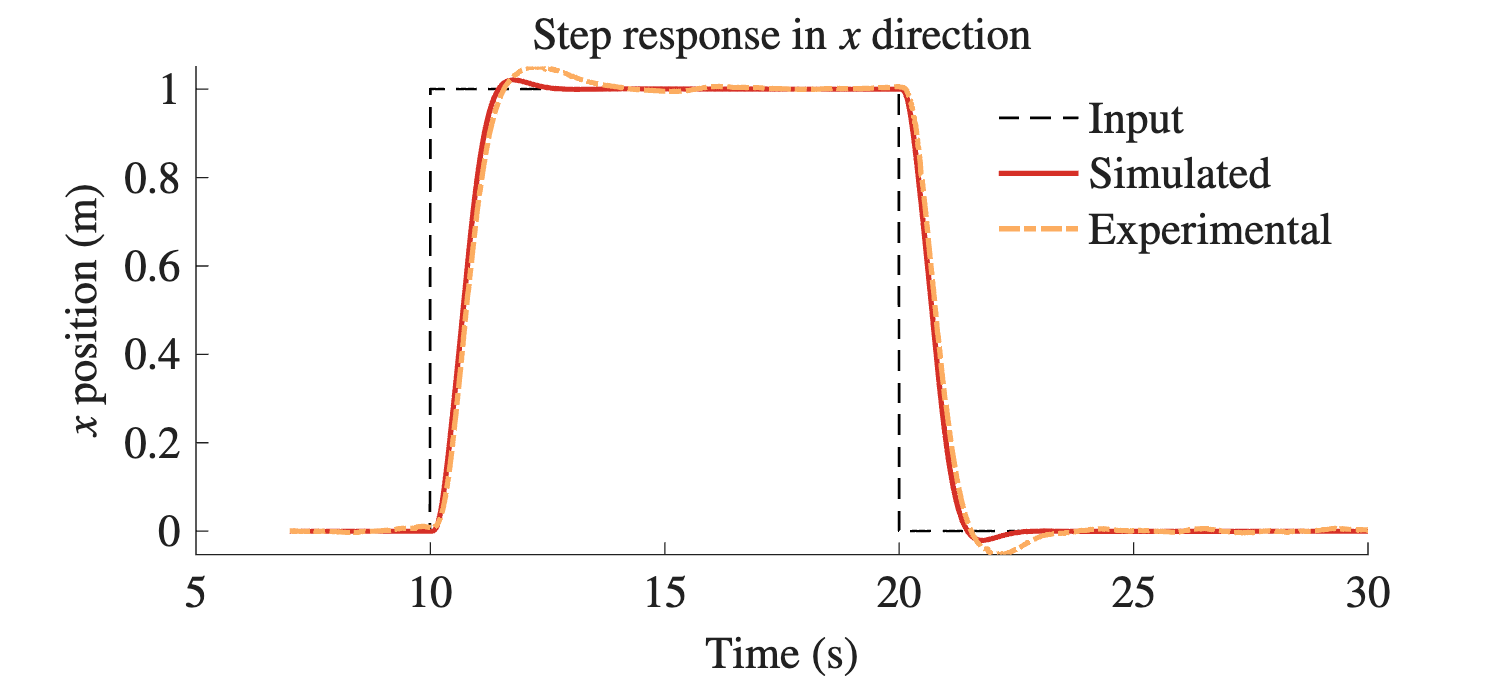

hfig = figure(1); clf; hold on;  % save the figure handle in a variable

plot(t(x_i0:x_if),input_x(x_i0:x_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(x_i0:x_if),sim_x(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if),true_x(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$x$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $x$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

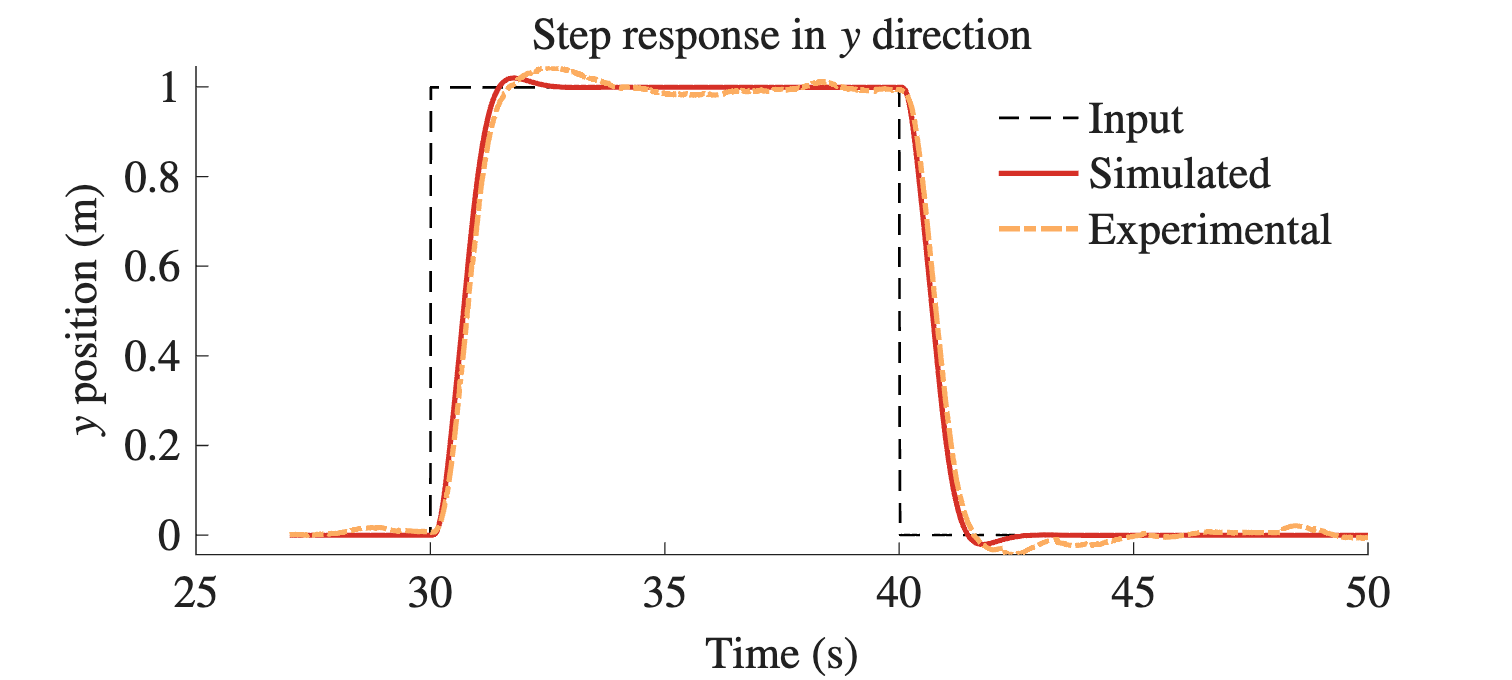

hfig = figure(2); clf; hold on;  % save the figure handle in a variable

plot(t(y_i0:y_if),input_y(y_i0:y_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(y_i0:y_if),sim_y(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if),true_y(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$y$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $y$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

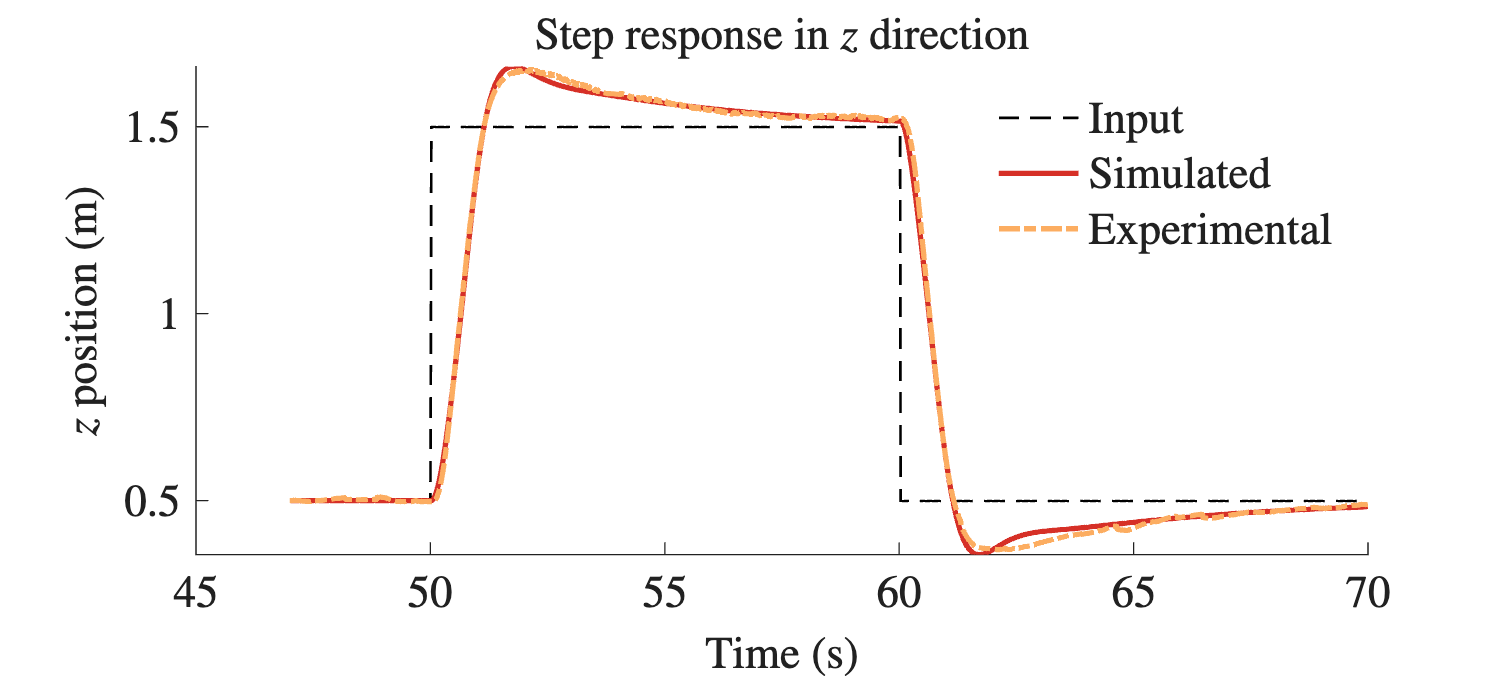

hfig = figure(3); clf; hold on;  % save the figure handle in a variable

plot(t(z_i0:z_if),input_z(z_i0:z_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(z_i0:z_if),sim_z(z_i0:z_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(z_i0:z_if),true_z(z_i0:z_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$z$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $z$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

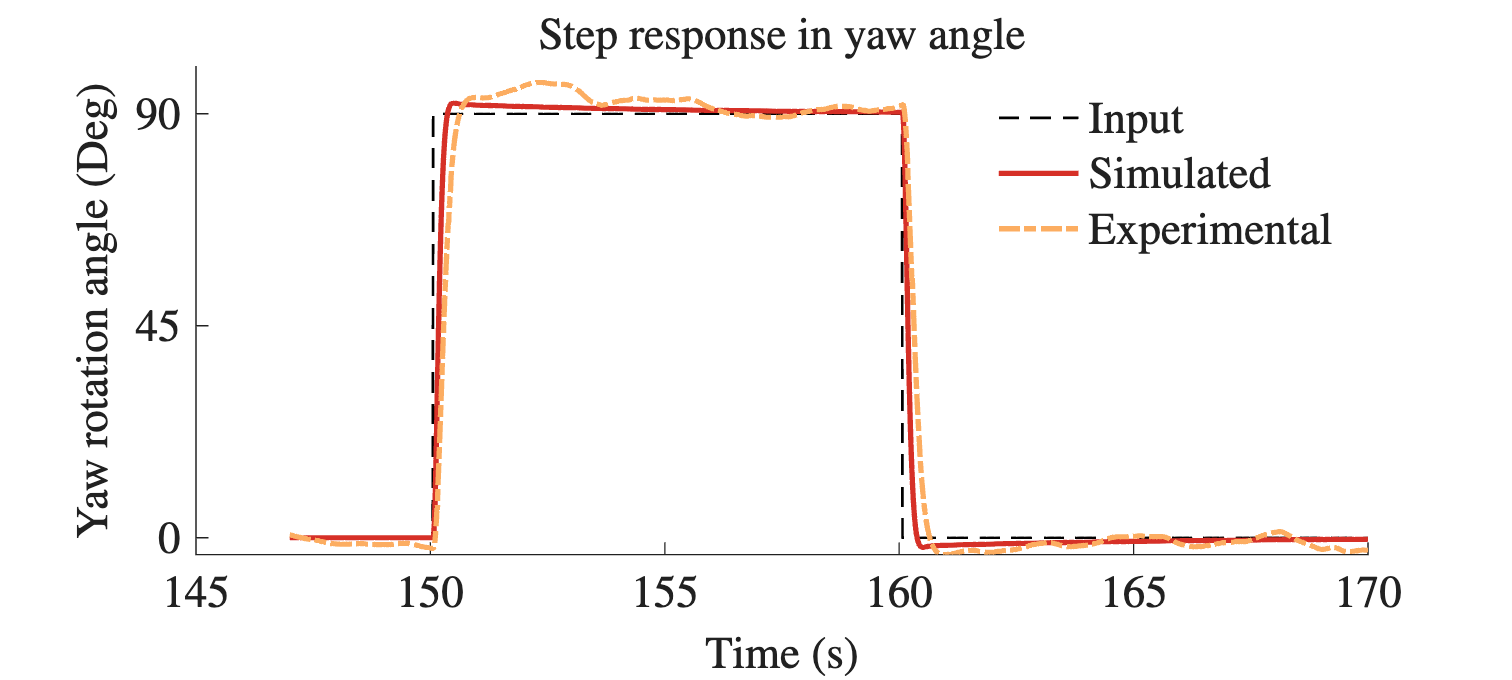

hfig = figure(4); clf; hold on;  % save the figure handle in a variable

plot(t(yaw_i0:yaw_if),input_yaw(yaw_i0:yaw_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(yaw_i0:yaw_if),sim_yaw(yaw_i0:yaw_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(yaw_i0:yaw_if),true_yaw(yaw_i0:yaw_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw rotation angle (Deg)')
yticks([0, 45, 90])
legend('Input', 'Simulated', 'Experimental')
title('Step response in yaw angle')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

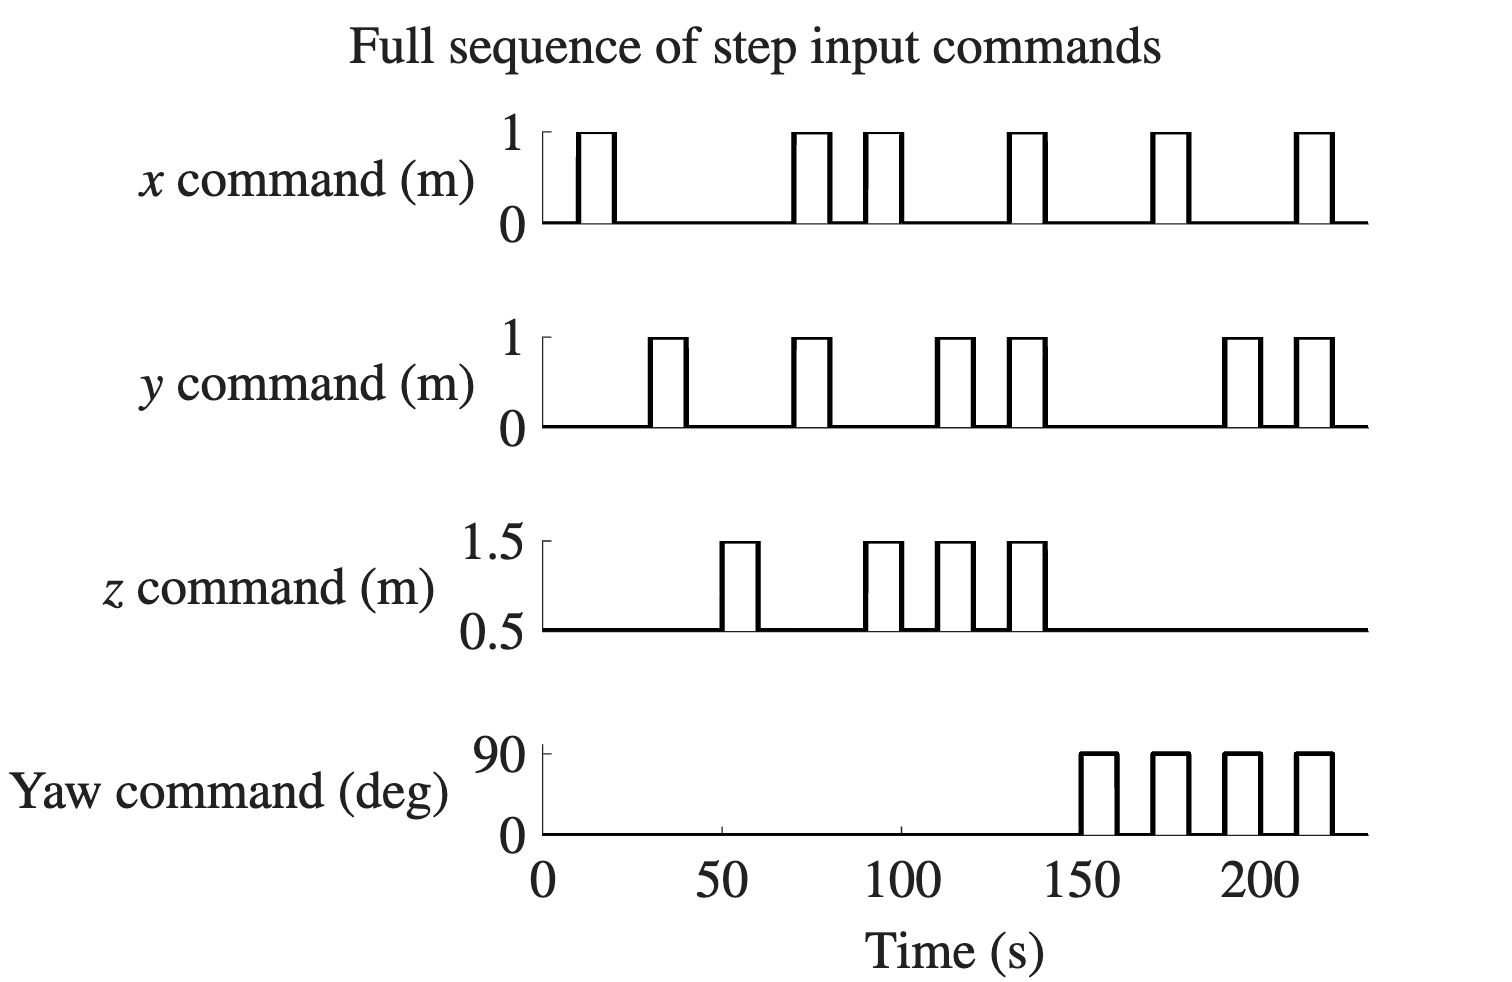

hfig = figure(5); clf; hold on;  % save the figure handle in a variable


subplot(4, 1, 1)
plot(t,input_x, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
yticks([0, 1])
ylabel('$x$ command (m)', 'Rotation', 0)
subplot(4, 1, 2)
plot(t,input_y, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
yticks([0, 1])
ylabel('$y$ command (m)', 'Rotation', 0)
subplot(4, 1, 3)
plot(t,input_z, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
ylabel('$z$ command (m)', 'Rotation', 0)
yticks([0.5, 1.5])
ylim([0.49 1.5])
subplot(4, 1, 4)
plot(t,input_yaw, 'Color', black, 'LineStyle','-','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw command (deg)', 'Rotation', 0)
yticks([0, 90])
fname = 'myfigure';

sgtitle('Full sequence of step input commands')

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.65; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',20) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

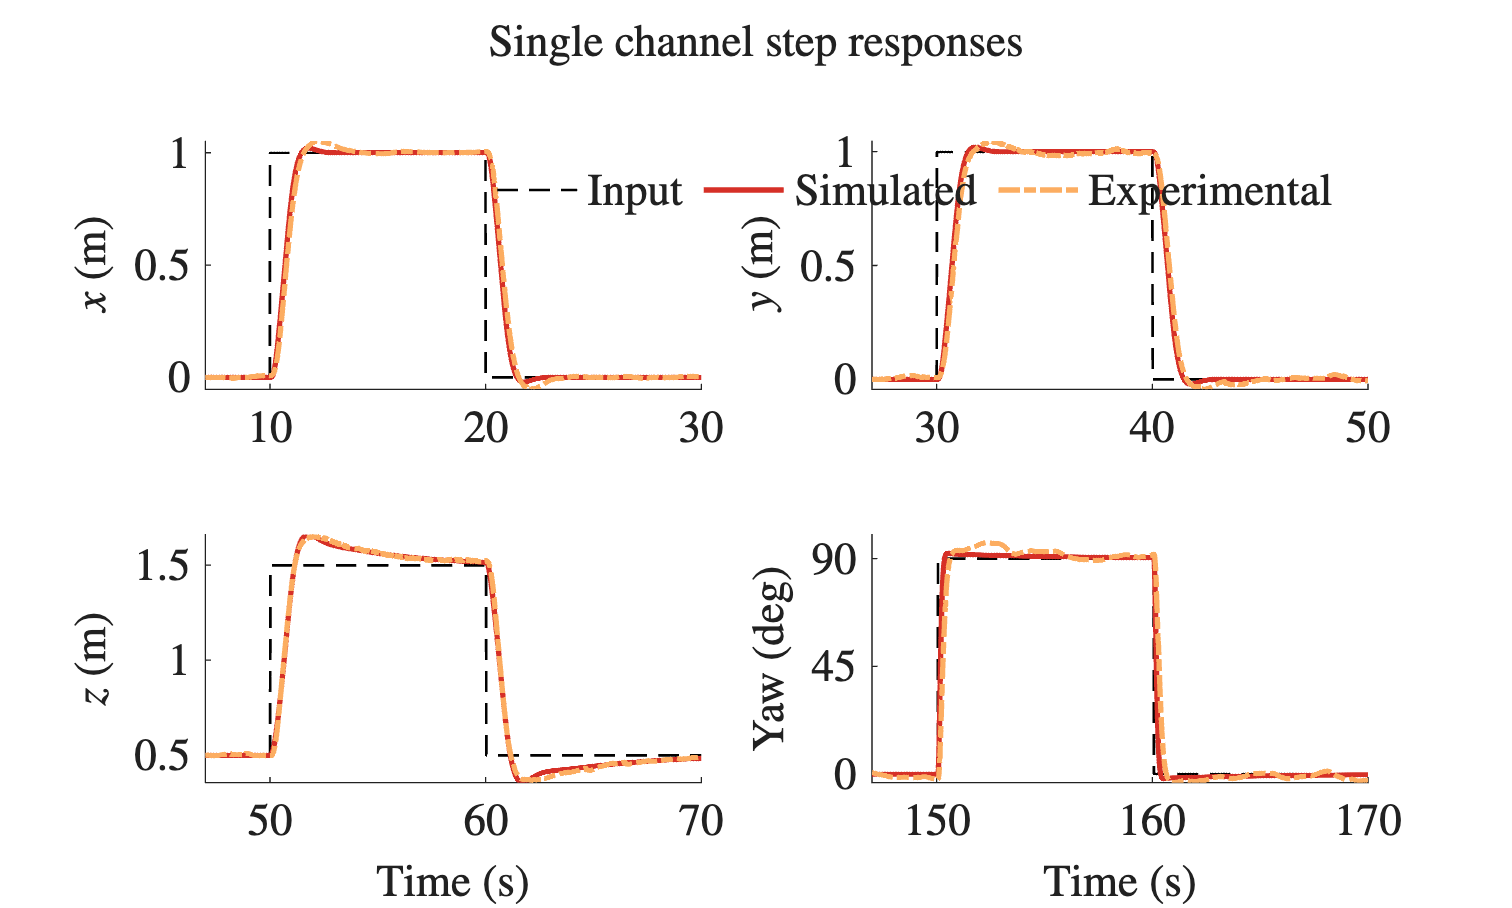

hfig = figure(5); clf; hold on;  % save the figure handle in a variable


subplot(2, 2, 1), hold on
plot(t(x_i0:x_if),input_x(x_i0:x_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(x_i0:x_if),sim_x(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if),true_x(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
ylabel('$x$ (m)')
hold off
subplot(2, 2, 2), hold on
plot(t(y_i0:y_if),input_y(y_i0:y_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(y_i0:y_if),sim_y(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if),true_y(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
ylabel('$y$ (m)')
legend('Input', 'Simulated', 'Experimental','Orientation', 'horizontal')
hold off
subplot(2, 2, 3), hold on
plot(t(z_i0:z_if),input_z(z_i0:z_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(z_i0:z_if),sim_z(z_i0:z_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(z_i0:z_if),true_z(z_i0:z_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$z$ (m)')
yticks([0.5, 1, 1.5])
hold off
subplot(2, 2, 4), hold on
plot(t(yaw_i0:yaw_if),input_yaw(yaw_i0:yaw_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(yaw_i0:yaw_if),sim_yaw(yaw_i0:yaw_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(yaw_i0:yaw_if),true_yaw(yaw_i0:yaw_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw (deg)')
yticks([0, 45, 90])
hold off
fname = 'myfigure';

sgtitle({'Single channel step responses', ''})

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.6; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

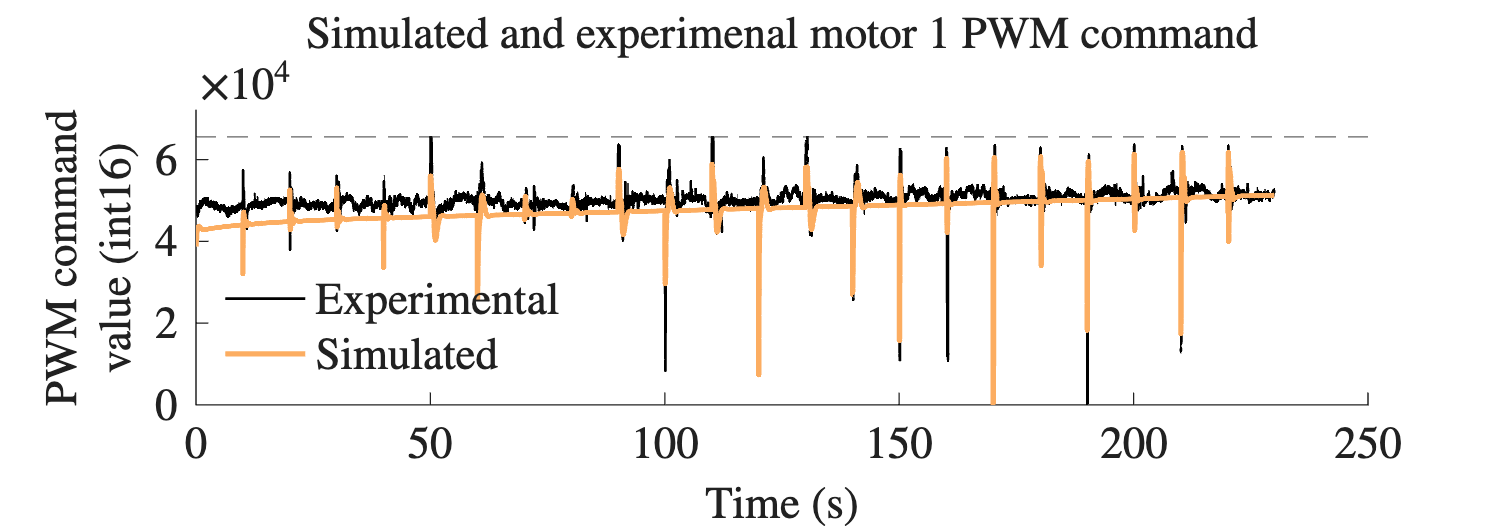

hfig = figure(6); clf; hold on;  % save the figure handle in a variable

plot(t,true_m1, 'Color', black, 'LineStyle','-','LineWidth',1);
plot(t,sim_m1, 'Color', orange, 'LineStyle','-','LineWidth',2);
xlabel('Time (s)')
ylabel({'PWM command', 'value (int16)'})
ylim([0 72000])
yline(65535, 'LineStyle','--')
legend({'Experimental', 'Simulated'}, 'Location','southwest');
title({'Simulated and experimenal motor 1 PWM command', ''})
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.35; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

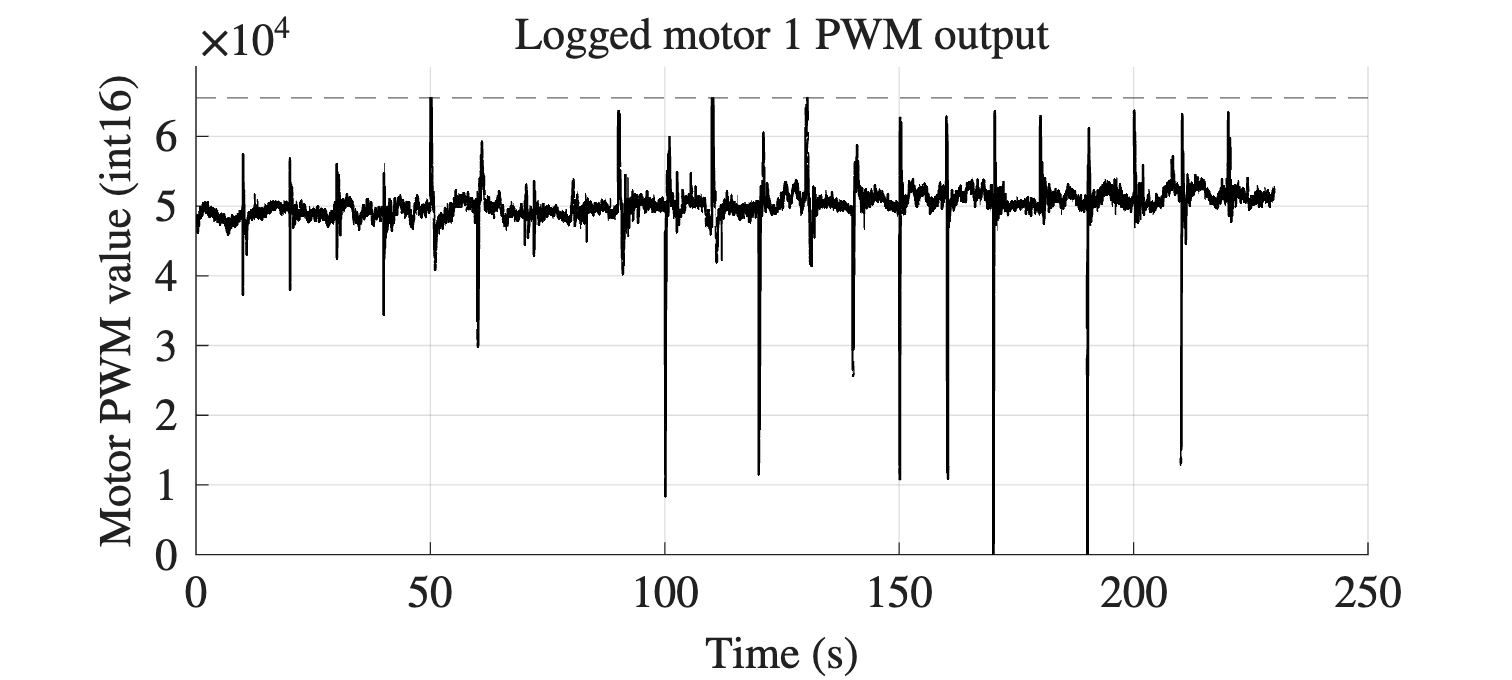

hfig = figure(7); clf; hold on;  % save the figure handle in a variable

plot(t,true_m1, 'Color', black, 'LineStyle','-','LineWidth',1);
% plot(t,true_m2, 'Color', orange, 'LineStyle','-','LineWidth',1);
% plot(t,true_m3, 'Color', red, 'LineStyle','-','LineWidth',1);
% plot(t,true_m4, 'LineStyle','-','LineWidth',1);
xlabel('Time (s)')
ylabel('Motor PWM value (int16)')
ylim([0 70000])
yline(65535, 'LineStyle','--')
title('Logged motor 1 PWM output')
yticks([0 10000 20000 30000 40000 50000 60000])
grid on
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

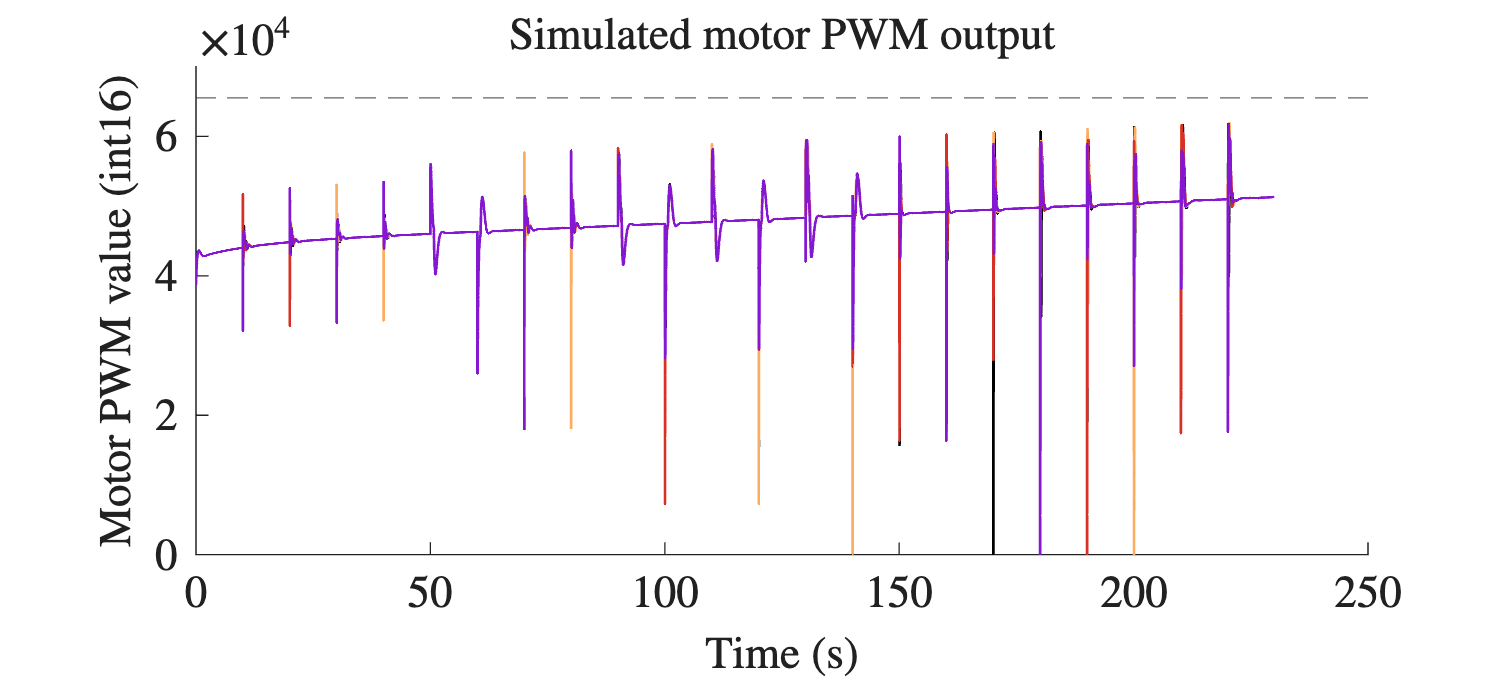

hfig = figure(8); clf; hold on;  % save the figure handle in a variable

plot(t,sim_m1, 'Color', black, 'LineStyle','-','LineWidth',1);
plot(t,sim_m2, 'Color', orange, 'LineStyle','-','LineWidth',1);
plot(t,sim_m3, 'Color', red, 'LineStyle','-','LineWidth',1);
plot(t,sim_m4, 'LineStyle','-','LineWidth',1);
xlabel('Time (s)')
ylabel('Motor PWM value (int16)')
ylim([0 70000])
yline(65535, 'LineStyle','--')
title('Simulated motor PWM output')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

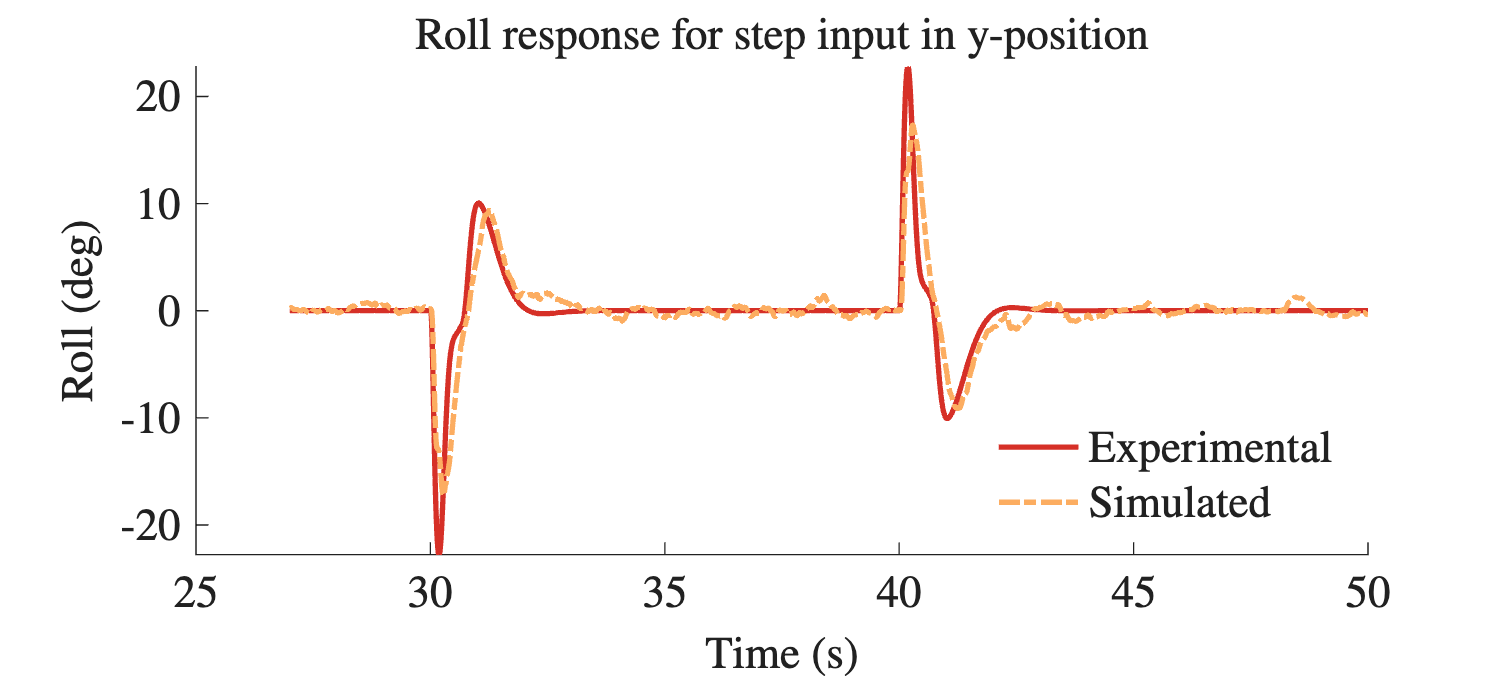

hfig = figure(9); clf; hold on;  % save the figure handle in a variable
plot(t(y_i0:y_if), sim_roll(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if), true_roll(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Roll (deg)')
legend({'Experimental', 'Simulated'}, 'Location','southeast');
title('Roll response for step input in y-position')

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

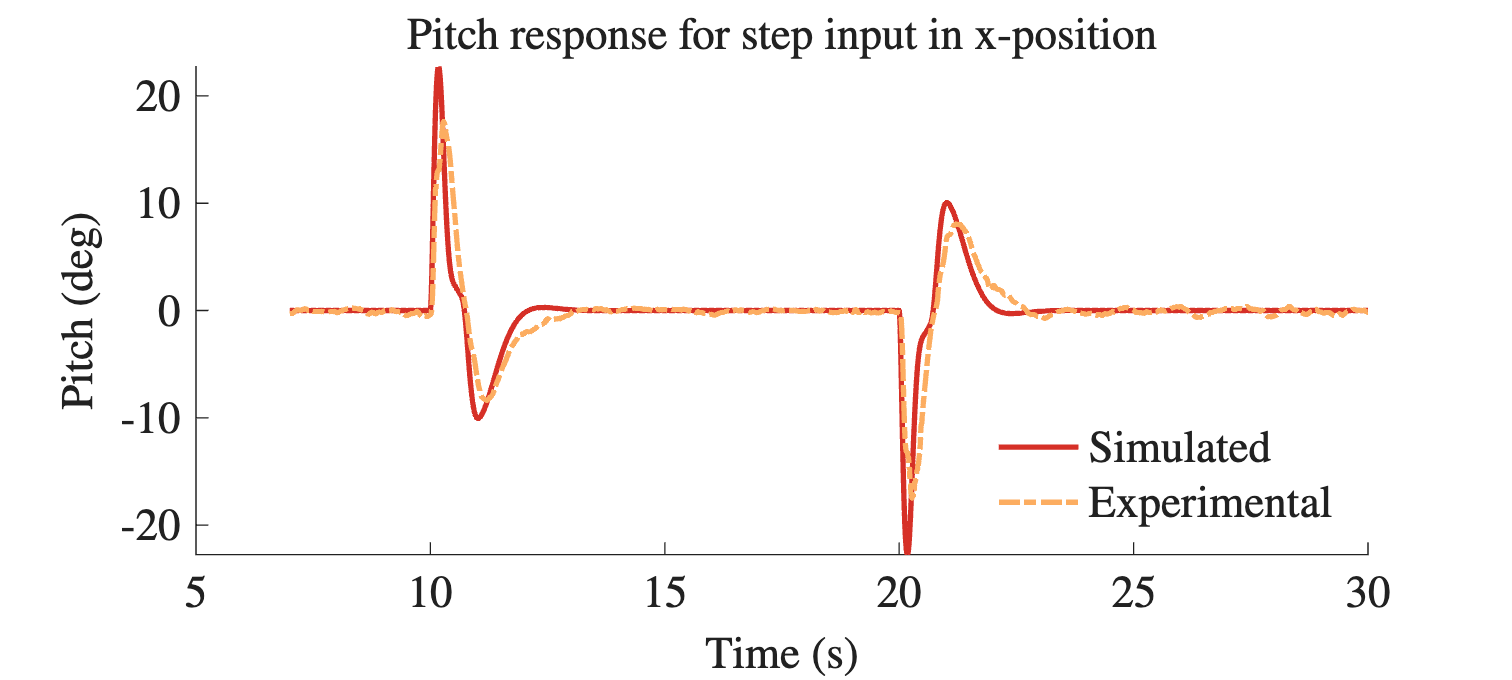

hfig = figure(10);clf;hold on;
plot(t(x_i0:x_if), sim_pitch(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if), true_pitch(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Pitch (deg)')
legend({'Simulated', 'Experimental'}, 'Location','southeast');
title('Pitch response for step input in x-position')

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;

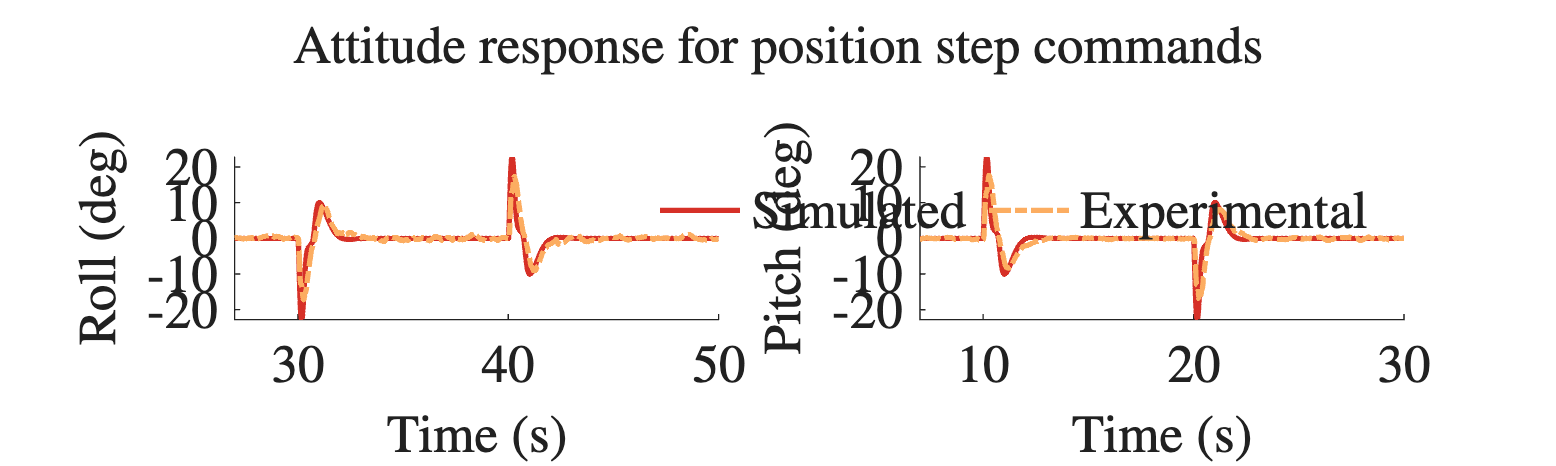

hfig = figure(11); clf; hold on;  % save the figure handle in a variable


subplot(1, 2, 1), hold on
plot(t(y_i0:y_if),sim_roll(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if),true_roll(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
yticks([-20 -10 0 10 20]);
xlabel("Time (s)")
ylabel('Roll (deg)')
hold off
subplot(1, 2, 2), hold on
plot(t(x_i0:x_if), sim_pitch(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if), true_pitch(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
yticks([-20 -10 0 10 20]);
xlabel("Time (s)")
ylabel('Pitch (deg)')
legend('Simulated', 'Experimental','Orientation', 'horizontal')
hold off
fname = 'myfigure';

sgtitle({'Attitude response for position step commands', ''})

picturewidth = 25; % set this parameter and keep it forever
hw_ratio = 0.3; % feel free to play with this ratio
set(findall(hfig,'-property','FontSize'),'FontSize',20) % adjust fontsize to your document

set(findall(hfig,'-property','Box'),'Box','off') % optional
set(findall(hfig,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig,'Position');
set(hfig,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-vector','-fillpage')
print(hfig,fname,'-dpng','-vector')

hold off;